# Coffee Model: Analytical Solution

Our mathematicl model to predict the dynamics.  We used Newton's Law of Cooling.


$$\dot{y}(t)=-k\,(y(t) - e)$$



$$y(0)=y_o$$


where $k$ is the constant cooling rate and $e$ is the constant environmental temperature and $y_o$ is the constant initial condition.

The analytical solution to this ODE is

$y(t) = e + (y_0 - e)  \, e^{-kt}$.

You may recognize the *time constant* as the characteristic decay time as $\tau = \frac{1}{k} $ min.

We can visualize the exact/analytical solution by sampling the continuous function.

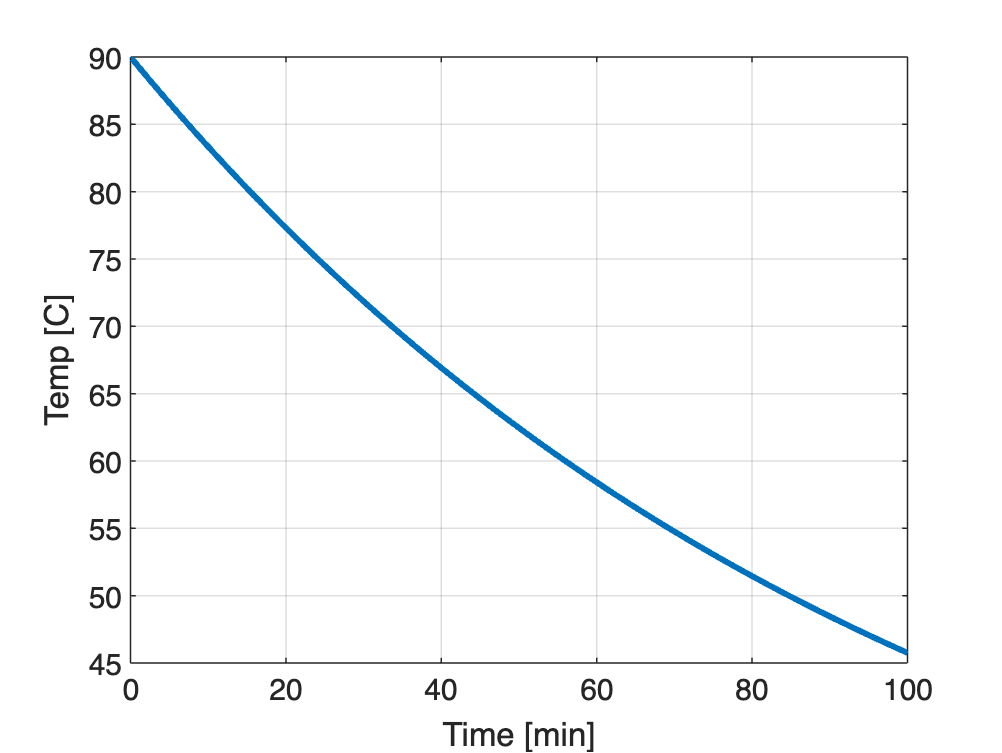

k = 0.01;   % degrees C / min
e = 20;    % C
y0 = 90;   % C
tt = linspace(0,100,1000);
figure(1);
clf();
plot(tt, e + (y0-e)*exp(-k*tt), 'linewidth', 2, ...
    'DisplayName', "Analytical")
grid("on")
xlabel("Time [min]")
ylabel("Temp [C]")